# Tarea: Aplicación de KPCA a distintas bases de datos.

#### Juan Uriel Legaria Peña

En esta tarea se abordará el fundamento detrás de KPCA (Kernel Principal Component Analysis) y se aplicará para la reducción de características en las siguientes bases de datos:

- Fisher Iris dataset (3 clases 4 variables)

- MNIST (10 clases 400 variables)

- Wine dataset: (3 clases, 14 variables)

### 1.- Fundamento de KPCA (Investigación)

La verdad en una primera lectura me había costado algo de trabajo entender KPCA, pero examinando mas a fondo el fundamento matemático este realmente no es muy complicado. 

La idea, como se dijo en clase es lllevar los datos a un espacio de mayor dimensión donde sea separable. Y el punto importante, que puede resultar un poco confuso si no conocemos los detalles, es que no es necesario hacer explicitamente la transformación de los datos al nuevo espacio. 

Lo primero que requerimos es el kernel $\bf{K} $, una matriz que contiene el producto punto de los distintos vectores en el nuevo espacio: Existen varios Kernels a nuestra disposición, algunos de ellos son:

- Gaussiano $\mathbf{K}_{ij} = \exp{(-\beta ||\mathbf{x}_{i}-\mathbf{x}_{j} ||)}$. Donde $\beta
$ es un parámetro del Kernel.

- Polinomial$\mathbf{K}_{ij} = (1+\mathbf{x}_{i}\cdot \mathbf{x}_{j})^{p}$. Donde $p$ es el grado del polinomio.

- Tangente hiperbólico $\mathbf{K}_{ij} = \tanh{(\mathbf{x}_{i}\cdot\mathbf{x}_{j}} + \delta)}$ con $\delta$ un parámetro del Kernel.

Una vez obtenida la matriz $\mathbf{K}$ debemos normalizarla. Esto lo hacemos porque aplicaremos un truco que requiere trabajar con datos transformados de media cero. La normalización se realiza de la siguiente manera:


$$\tilde{\mathbf{K}} = \mathbf{K}-2\mathbf{I}_{1/m}\mathbf{K} + \mathbf{I}_{1/m}\mathbf{K}\mathbf{I}_{1/m}$$


Donde $\mathbf{I}_{1/m}$ es una matriz que contiene 1/m en todas sus entradas. m sería el número de observaciones o datos con los que contamos.

En vez de utilizar la notación $\tilde{\mathbf{K}}$, seguiremos escribiendo $\mathbf{K}$ bajo el entendido de que esta ya se encuentra normalizada.

Sea $\phi(\mathbf{x}_{i})$ la transformación al vector $\mathbf{x}_{i}$, La matriz de covarianza en el espacio transformado toma la siguiente forma::


$$\mathbf{C} =\frac{1}{m}\sum_{i = 1}^{m}\phi(\mathbf{x}_{i})\phi(\mathbf{x}_{i})^{T}$$


Notese que ya no aparece la media restada, ya que despues de normalizar esta es igual a cero.

Ahora, nuestra ecuación de eigenvalores se vería de la siguiente forma:


$$\sum_{i = 1}^{m}\phi(\mathbf{x}_{i})\phi(\mathbf{x}_{i})^{T} \mathbf{v} = \lambda m \mathbf{v}$$


Lo que ahoremos ahora será expresar estos eigenvectores como combinación lineal de los datos transformados, i.e. el eigenvector j-ésimo $\mathbf{v}_{j}$ se expresaría de la siguiente forma:


$$\mathbf{v}_{j} = \sum_{l=0}^{m}a_{jl}\phi(\mathbf{}x)_{l}$$


Sustituyendo en la ecuación de eigenvalores:


$$\sum_{i = 1}^{m}\phi(\mathbf{x}_{i})\phi(\mathbf{x}_{i})^{T} \left(\sum_{l=0}^{m}a_{jl}\phi(\mathbf{}x)_{l}\right) = \lambda_{j} m \left(\sum_{l=0}^{m}a_{jl}\phi(\mathbf{}x)_{l}\right)$$


Como $K(\mathbf{x}_{i},\mathbf{x}_{l}) = \phi(\mathbf{x}_{i})^{T}\phi(\mathbf{x}_{l})$:


$$\sum_{i = 1}^{m}\phi(\mathbf{x}_{i})\sum_{l=0}^{m}a_{jl}K(\mathbf{x}_{i}, \mathbf{x}_{l}) = \lambda_{j} m \left(\sum_{l=0}^{m}a_{jl}\phi(\mathbf{}x)_{l}\right)$$


Ahora hacemos un truco y multiplicamos a la izquierda toda la ecuación por $\phi(\mathbf{x}_{k})^{T}$, donde k es un indice independiente de los ya existentes i, l, j. Se tiene así:


$$\sum_{i = 1}^{m}K(\mathbf{x}_{k}, \mathbf{x}_{i})\sum_{l=0}^{m}a_{jl}K(\mathbf{x}_{i}, \mathbf{x}_{l}) = \lambda_{j} m \sum_{l=0}^{m}a_{jl}K(\mathbf{x}_{k},\mathbf{x}_{l})$$


En notación matricial esto se puede escribir como


$$\mathbf{K}^2 \mathbf{a}_{j} = m\lambda_{j}\mathbf{K}\mathbf{a}_{j}$$


Multiplicando a ambos lados por la inversa de $\mathbf{K}$:


$$\mathbf{K} \mathbf{a}_{j} = m\lambda_{j}\mathbf{a}_{j}$$


Lo anterior quiere decir que los vectores $\mathbf{a}_{j}$ son eigen vectores de la matriz $\mathbf{K}$, y estos los podemos utilizar para obtener la proyección en las componentes principales mediante la siguiente ecuación:


$$\phi(\mathbf{x})^{T} \mathbf{v}_{j}= \sum_{i} a_{ji} \phi(\mathbf{x})^{T}\phi(\mathbf{x}_{j}) = \sum_{i}a_{ji}K(\mathbf{x},\mathbf{x}_{i})$$


Resumiendo, los pasos a seguir serían:

- Construir la matriz $\mathbf{K}$usando el Kernel deseado

- Normalizar la matriz $\mathbf{K
}$

- Obtener los eigenvalores y eigenvectores de dicha matriz.

- Proyectar estos eigenvectores directamente en el espacio transformado usando el truco del Kernel


$$y = \sum_{i}a_{ji}K(\mathbf{x},\mathbf{x}_{i})$$


### 2.- Implementación

La implementación realizada consta de las siguientes clases:

- *DataPrecook*: Clase dedicada a tareas de preprocesamiento, como la normalización de los datos. 

- *KernelType*: Clase tipo Enum para categorizar los diferentes tipos de Kernel. Los valores posibles que se implementaron fueron KernelType.POLYNOMIAL y KernelType.GAUSSIAN.

- *KernelCalculator: *Clase que contiene los métodos requeridos para el cálculo de la matriz $\mathbf{K}$ y su normalización.

- *KPCAAnalyzer: *Clase que realiza el análisis de componentes principales utilizando el truco del Kernel. Esta cuenta ocn dos métodos: computeComponentes: Calcula los eigenvectores y eigenvalores de la matriz **K**, y los almacena como una propiedad del objeto. projectOriginalData proyecta los datos en un número de componentes principales especificadas por el usuario. 

### 3.- Fisher Dataset

#### 3.1.- Normalización y visualización de los datos

Seria bueno primero observar los datos, para ver si realmente tenemos varias correlaciones no lineales, en cuyo caso beneficiará el uso de KPCA. 

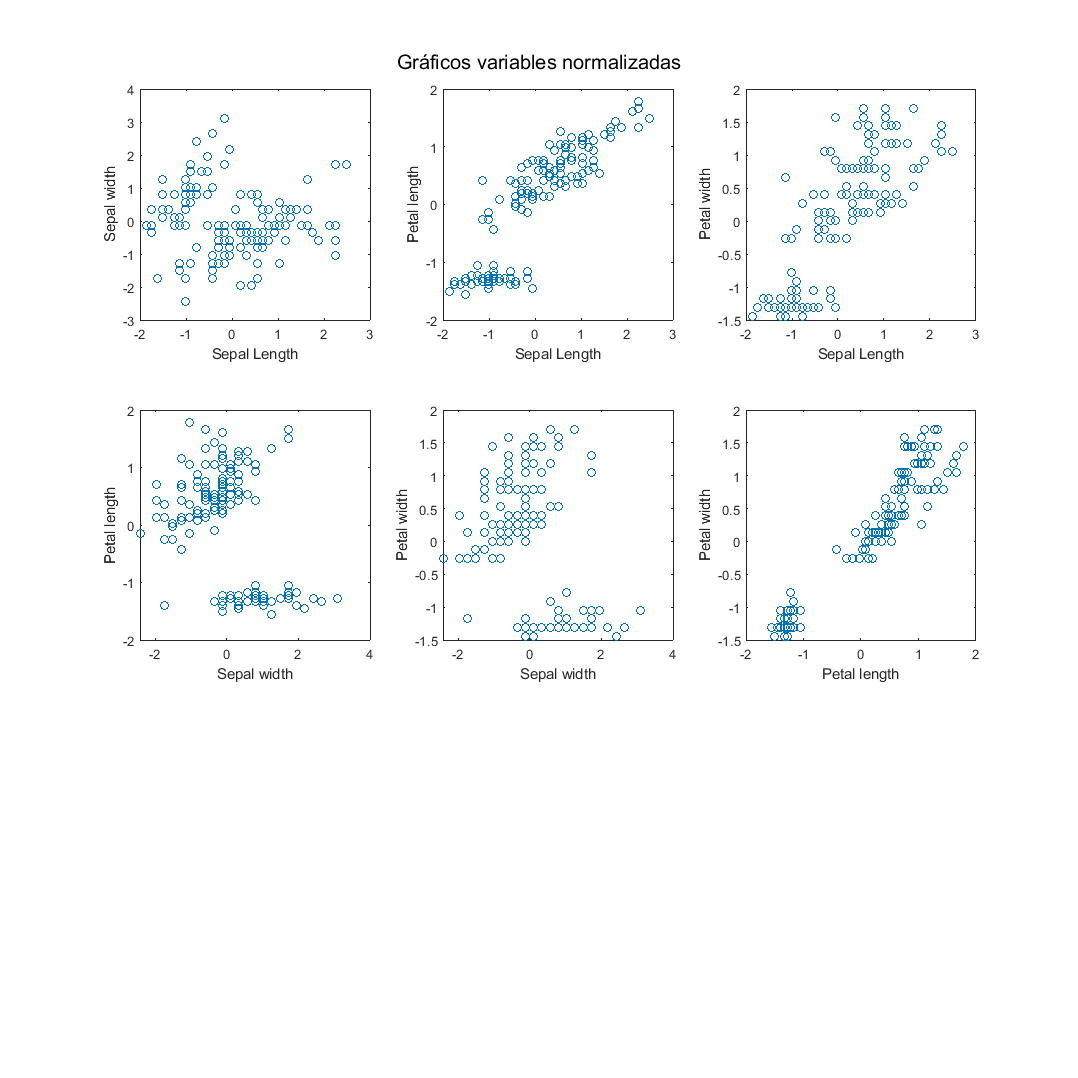

%Abrimos los datos y los ponemos en forma conveniente
%en una tabla
flowerRawData = importdata('iris.data');
n = length(flowerRawData);
flowerClassArray = zeros(n,1);
flowerDataArray = zeros(n,4);
for i = 1:n
    str = flowerRawData{i};
    vector = split(str, ',');
    %Recolectamos las diferentes características
    %en nuestra tabla
    flowerDataArray(i,1) = str2double(vector(1));
    flowerDataArray(i,2) = str2double(vector(2));
    flowerDataArray(i,3) = str2double(vector(3));
    flowerDataArray(i,4) = str2double(vector(4));
    %Ahora vamos a ver la clase vamos a hacer la siguiente
    %asignación 0: Iris-setosa 1: Iris-versicolor 2: Iris-virginica
    classString = vector(5);
    classNumber = -1;
    if(classString == "Iris-setosa")
        classNumber = 0;
    elseif(classString == "Iris-versicolor")
        classNumber = 1;
    elseif(classString == "Iris-virginica")
        classNumber = 2;
    end
    flowerClassArray(i) = classNumber;
end

flowerFeatureNames = ["Sepal Length", "Sepal width", "Petal length", "Petal width"];
%Número de vectores que contiene el dataset
nData = size(flowerDataArray, 1);
%Número de descriptores
nFeatures = size(flowerDataArray,2);
%Vamos a normalizar y graficar
normalizedFlowerData = zeros(nData, nFeatures);
numberOfGraphs = (nFeatures*(nFeatures - 1))/2;
m = floor(sqrt(numberOfGraphs));
n = 0;
if(m^2 < numberOfGraphs)
     n = floor(sqrt(numberOfGraphs)) + 1;
     m = floor(sqrt(numberOfGraphs)) +1;
else
    n = floor(sqrt(numberOfGraphs))
end
%Creamos el precalentador de datos
dataPrecooker = DataPrecook();
graphCounter = 1;
figure()
set(gcf,'units','points','position',[10,10,1200,1200])
sgtitle("Gráficos variables normalizadas")
hold on 
for i = 1:nFeatures
    normalizedX = dataPrecooker.normalize(flowerDataArray(:,i));
    normalizedFlowerData(:,i) = normalizedX;
    for j = i+1:nFeatures
        
        normalizedY = dataPrecooker.normalize(flowerDataArray(:,j));
        subplot(n,m, graphCounter)
        plot(normalizedX, normalizedY, 'o')
        xlabel(flowerFeatureNames(i))
        ylabel(flowerFeatureNames(j))
        graphCounter = graphCounter + 1;
    end
end
hold off

Algunas de estas variables parecen ser correlacionarse linealmente, sin embargo varias de ellos no siguen tendencias lineales. A continuación procederé a hacer el análisis de componentes principales usando primero un Kernel Gaussiano, y posteriormente uno polinomial lineal (que correspondería a PCA sin Kernel). Acorde a la información provista en el dataset, 2 de las clases deberian ser linealmetne separables, mientras que la separación de la tercera solo se debería apreciar con KPCAl.

#### 3.2.- Aplicación de KPCA

Primeras dos componentes 0.20952


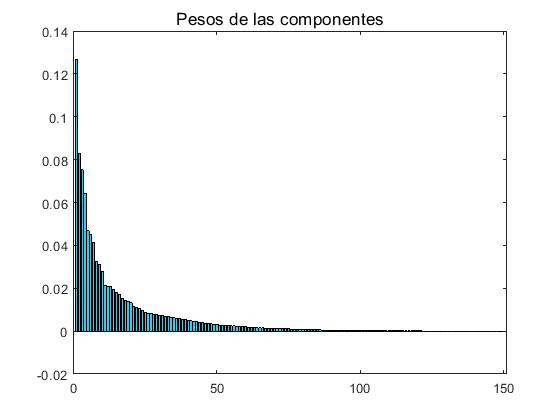

kernelType = KernelType.GAUSSIAN;
beta = 1.655;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedFlowerData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

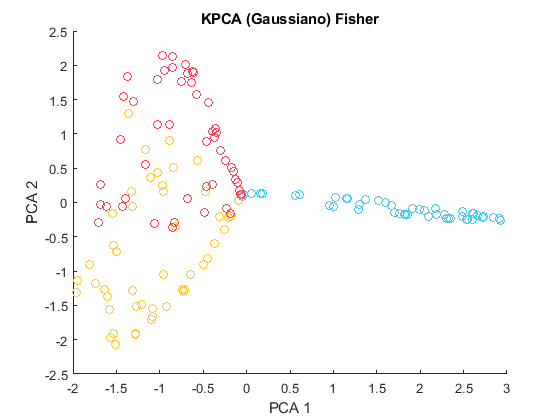

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedFlowerData, 2);
color1 = "#47ccf5";
color2 = "#ffcb30";
color3 = "#ff455b";
figure()
title("KPCA (Gaussiano) Fisher")
hold on 
for i = 1:nData
    point = projectedData(i,:);
    if(flowerClassArray(i) == 0)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(flowerClassArray(i) == 1)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(flowerClassArray(i) == 2)
        plot(point(1), point(2), 'o', 'color', color3)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

Dentro de todo observamos que la separación entre las 3 clases se logra bastante bien, Aunque se observa cierto traslape entre los puntos que corresponden a la clase roja (Iris-virginica) y la amarilla (Iris-versicolor). Esto podría mejorarse tomando una mayor cantidad de componentes. Por el momento se ha trabajado con 2, ya que así se facilita mejor la visualización.

#### 3.3.- PCA

Ahora hagamos PCA pero con un Kernel lineal, a ver que se obtiene.

Primeras dos componentes 0.95801


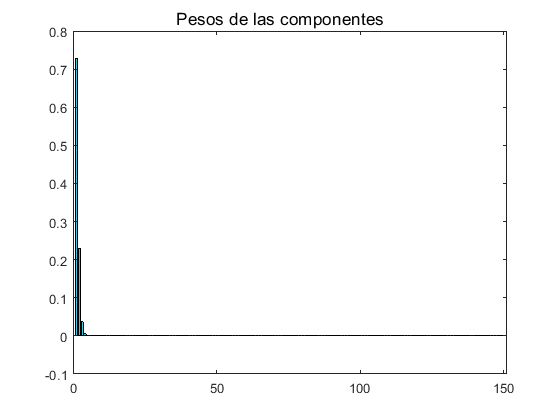

kernelType = KernelType.POLYNOMIAL;
beta = 1;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedFlowerData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

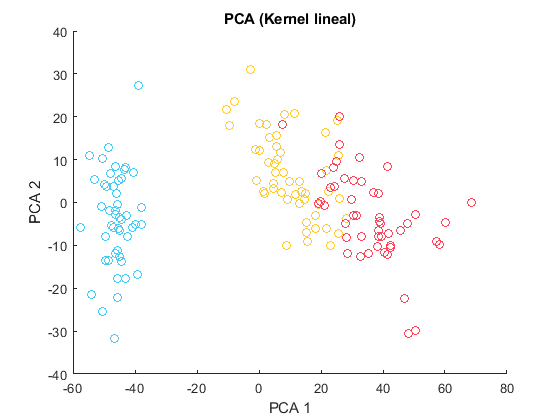

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedFlowerData, 2);
color1 = "#47ccf5";
color2 = "#ffcb30";
color3 = "#ff455b";
figure()
title("PCA (Kernel lineal)")
hold on 
for i = 1:nData
    point = projectedData(i,:);
    if(flowerClassArray(i) == 0)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(flowerClassArray(i) == 1)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(flowerClassArray(i) == 2)
        plot(point(1), point(2), 'o', 'color', color3)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

Vemos que la simetría radial del kernel gaussiano nos permite hacer una división de los puntos como si estos se hallaran en una especie de pastel con 3 rebanadas, lo cual mejora un poco la separación. Aun así no logré hacer una separación completa como la que se muestra en algunos ejemplos de internet con el dataset de Fisher, pienso que hay algún detalle de escala que podría estar ignorando dentro de mi implementación de KPCA.

### 4.- Base de datos MNIST

Comenzamos con la apertura de datos. Dado que MNIST es un dataset muy grande, reduciremos el número de imagenes a procesar a un número mas manejable para nuestro algoritmo de KPCA. 

mnistData = importdata("train.csv", ",");
nImages = 1000;
mnistReduced = mnistData.data(1:nImages, 2:end);
mnistReducedLabels = mnistData.data(1:nImages,1);
%Normalicemos
normalizedMnistData = zeros(size(mnistReduced,1), size(mnistReduced,2));
dataCooker = DataPrecook();
for i = 1:size(mnistReduced,2)
    normalizedMnistData(:,i) = dataCooker.normalize(mnistReduced(:,i)); 
end

#### 4.1.- KPCA 

Primeras dos componentes 0.044488


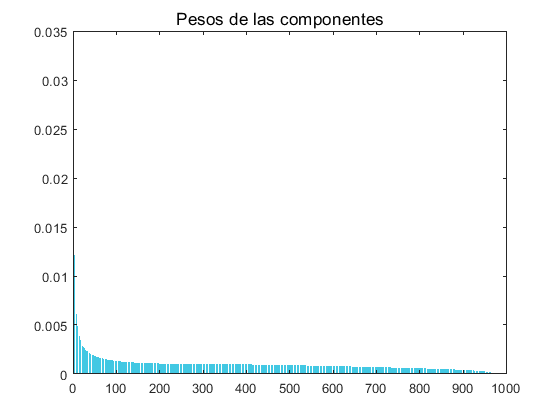

kernelType = KernelType.GAUSSIAN;
beta = 0.005;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedMnistData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

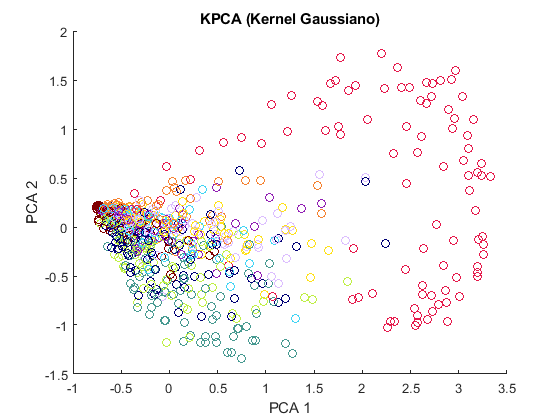

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedMnistData, 2);
color0 = "#800000";
color1 = "#e6194B";
color2 = "#f58231";
color3 = "#ffe119";
color4 = "#bfef45";
color5 = "#42d4f4";
color6 = "#911eb4";
color7 = "#000075";
color8 = "#dcbeff";
color9 = "#469990";
figure()
title("KPCA (Kernel Gaussiano)")
hold on 
for i = 1:nImages
    point = projectedData(i,:);
    if(mnistReducedLabels(i) == 0)
        plot(point(1), point(2), 'o', 'color', color0)
    elseif(mnistReducedLabels(i) == 1)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(mnistReducedLabels(i) == 2)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(mnistReducedLabels(i) == 3)
        plot(point(1), point(2), 'o', 'color', color3)
    elseif(mnistReducedLabels(i) == 4)
        plot(point(1), point(2), 'o', 'color', color4)
    elseif(mnistReducedLabels(i) == 5)
        plot(point(1), point(2), 'o', 'color', color5)
    elseif(mnistReducedLabels(i) == 6)
        plot(point(1), point(2), 'o', 'color', color6)
    elseif(mnistReducedLabels(i) == 7)
        plot(point(1), point(2), 'o', 'color', color7)
    elseif(mnistReducedLabels(i) == 8)
        plot(point(1), point(2), 'o', 'color', color8)
    elseif(mnistReducedLabels(i) == 9)
        plot(point(1), point(2), 'o', 'color', color9)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

#### 4.2.-PCA

Primeras dos componentes 0.11647


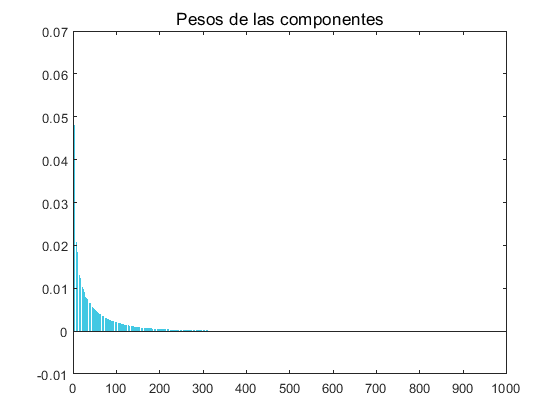

kernelType = KernelType.POLYNOMIAL;
beta = 1;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedMnistData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

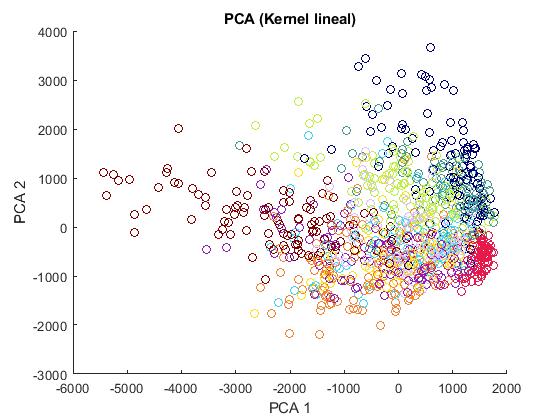

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedMnistData, 2);
color0 = "#800000";
color1 = "#e6194B";
color2 = "#f58231";
color3 = "#ffe119";
color4 = "#bfef45";
color5 = "#42d4f4";
color6 = "#911eb4";
color7 = "#000075";
color8 = "#dcbeff";
color9 = "#469990";
figure()
title("PCA (Kernel lineal)")
hold on 
for i = 1:nImages
    point = projectedData(i,:);
    if(mnistReducedLabels(i) == 0)
        plot(point(1), point(2), 'o', 'color', color0)
    elseif(mnistReducedLabels(i) == 1)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(mnistReducedLabels(i) == 2)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(mnistReducedLabels(i) == 3)
        plot(point(1), point(2), 'o', 'color', color3)
    elseif(mnistReducedLabels(i) == 4)
        plot(point(1), point(2), 'o', 'color', color4)
    elseif(mnistReducedLabels(i) == 5)
        plot(point(1), point(2), 'o', 'color', color5)
    elseif(mnistReducedLabels(i) == 6)
        plot(point(1), point(2), 'o', 'color', color6)
    elseif(mnistReducedLabels(i) == 7)
        plot(point(1), point(2), 'o', 'color', color7)
    elseif(mnistReducedLabels(i) == 8)
        plot(point(1), point(2), 'o', 'color', color8)
    elseif(mnistReducedLabels(i) == 9)
        plot(point(1), point(2), 'o', 'color', color9)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

Vemos que con KPCA hay ciertas clases que se contrastan, sin embargo las demás tienden a juntarse entre sí, lo cual nos habla de que probablemente este no sea el Kernel mas adecuado a utilizar. Linealmente, al menos para las dos componentes que se escogieron, tampoco se logra una separación satisfactoria de las clases. Aquí sería una cuestión de jugar aun mas con los datos, implementando y probando nuevos Kernels etc.

### 5.- Dataset de vinos 

Finalmente vamos a aplicar el método KPCA al dataset de vinos con el que se trabajo en tareas anteriores.  Comencemos con una observación de los datos, para examinar si existen correlaciones entre ellos y si son lineales o tienen alguna otra forma.

#### 5.1.- Normalización y visualización de datos

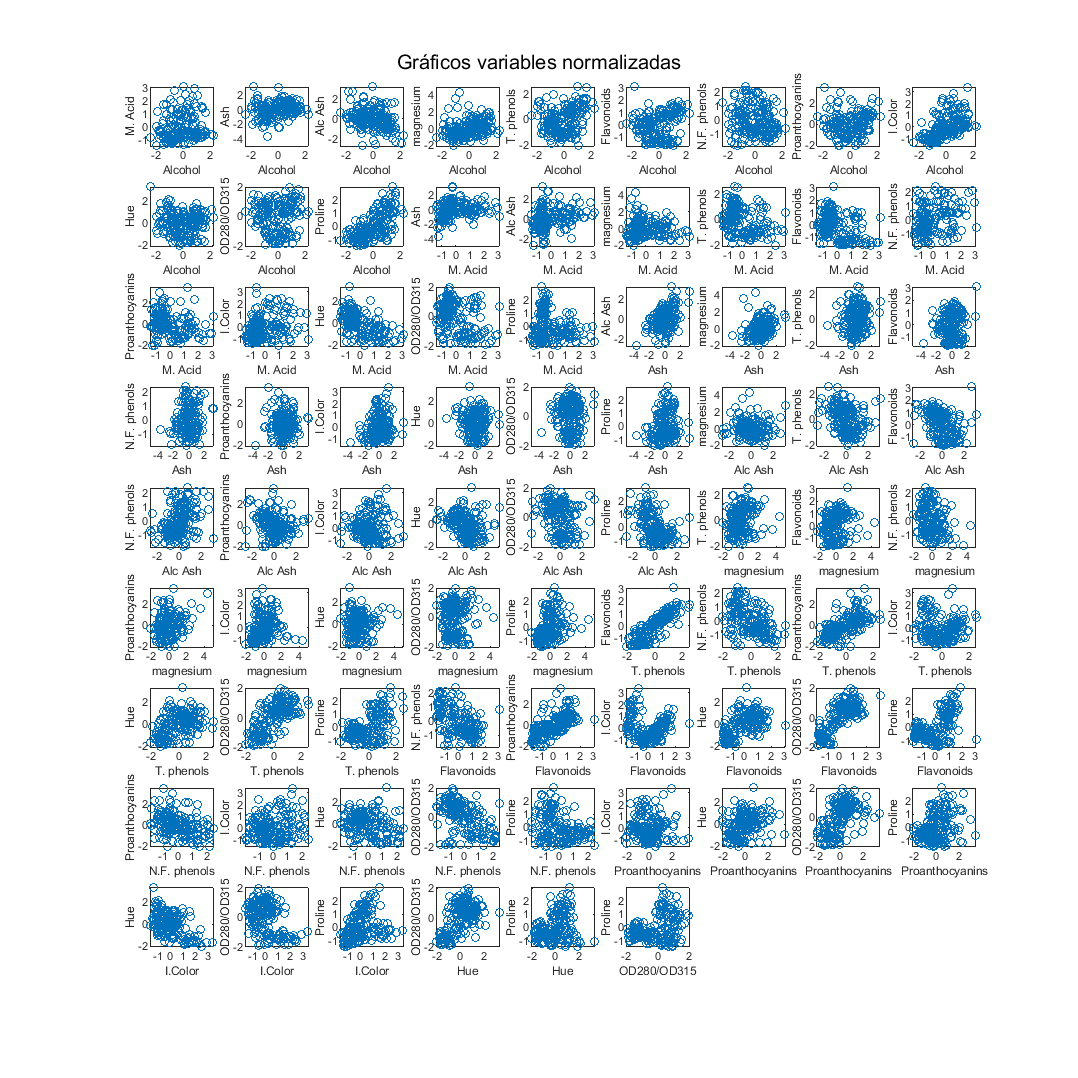

%Importamos los datos
data = importdata('wine.data');
wineClass = data(:,1);
wineData = data(:,2:end);
%Los nombres de las características para hacer los labels de las gráficas.
featureNames = ["Alcohol", "M. Acid", "Ash", "Alc Ash",...
    "magnesium", "T. phenols", "Flavonoids", "N.F. phenols",...
    "Proanthocyanins", "I.Color", "Hue", "OD280/OD315", "Proline"];
%Número de vectores que contiene el dataset
nData = size(wineData, 1);
%Número de descriptores
nFeatures = size(wineData,2);
%Vamos a normalizar y graficar
normalizedWineData = zeros(nData, nFeatures);
numberOfGraphs = (nFeatures*(nFeatures - 1))/2;
m = floor(sqrt(numberOfGraphs));
n = 0;
if(m^2 < numberOfGraphs)
     n = floor(sqrt(numberOfGraphs)) + 1;
     m = floor(sqrt(numberOfGraphs)) +1;
else
    n = floor(sqrt(numberOfGraphs))
end
%Creamos el precalentador de datos
dataPrecooker = DataPrecook();
graphCounter = 1;
figure()
set(gcf,'units','points','position',[10,10,1200,1200])
sgtitle("Gráficos variables normalizadas")
hold on 
for i = 1:nFeatures
    normalizedX = dataPrecooker.normalize(wineData(:,i));
    normalizedWineData(:,i) = normalizedX;
    for j = i+1:nFeatures
        
        normalizedY = dataPrecooker.normalize(wineData(:,j));
        subplot(n,m, graphCounter)
        plot(normalizedX, normalizedY, 'o')
        xlabel(featureNames(i))
        ylabel(featureNames(j))
        graphCounter = graphCounter + 1;
    end
end
hold off

#### 5.2.- Aplicación de KPCA

Primeras dos componentes 0.072456


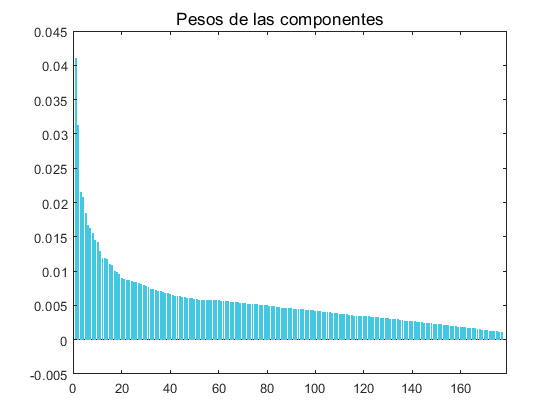

kernelType = KernelType.GAUSSIAN;
beta = 0.3;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedWineData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

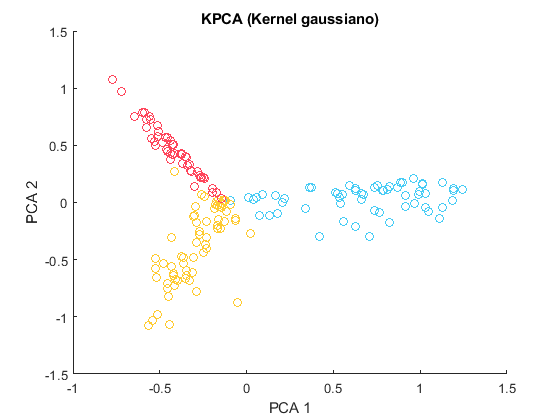

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedWineData, 2);
color1 = "#47ccf5";
color2 = "#ffcb30";
color3 = "#ff455b";
figure()
title("KPCA (Kernel gaussiano)")
hold on 
for i = 1:nData
    point = projectedData(i,:);
    if(wineClass(i) == 1)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(wineClass(i) == 2)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(wineClass(i) == 3)
        plot(point(1), point(2), 'o', 'color', color3)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

#### 5.2.- PCA

Apliquemos PCA como habiamos hecho en la tarea anterior para comparar. Ahora, sin embargo, veremos PCA como un caso particular de KPCA en el que se usa un kernel polinomial de grado 1. El resultado en cualquier caso debiese ser el mismo, y creo que puede ser útil como prueba de que el algoritmo implementado funciona correctamente.

Primeras dos componentes 0.55406


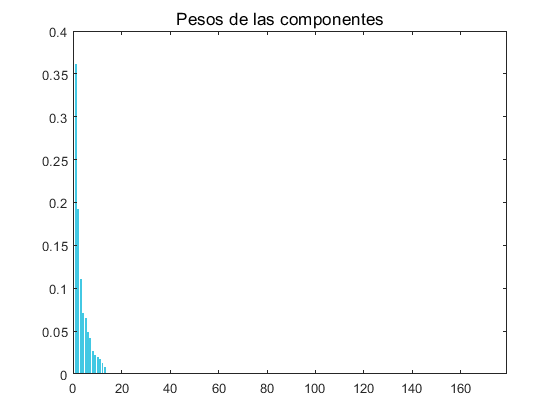

kernelType = KernelType.POLYNOMIAL;
beta = 1;
kernelCalculator = KernelCalculator();
%Obtenemos la matriz K normalizada
kMatrix = kernelCalculator.computeNormalizedK(normalizedWineData, kernelType, beta);
%Creamos el analizador de KPCA
kpcaAnalyzer = KPCAAnalyzer(kMatrix);
%Obtenemos las componentes principales
kpcaAnalyzer = kpcaAnalyzer.computeComponents();

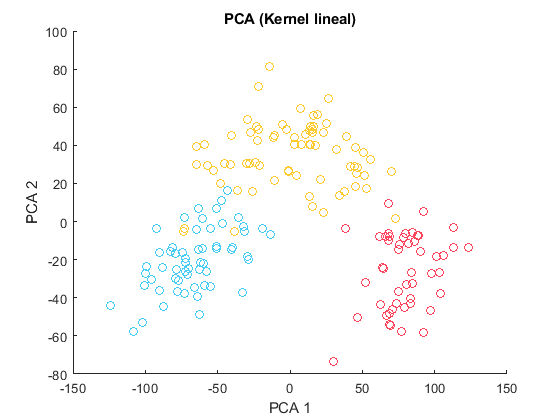

%Tomemonos solo dos componentes para poder visualizar
projectedData = kpcaAnalyzer.projectOriginalData(normalizedWineData, 2);
color1 = "#47ccf5";
color2 = "#ffcb30";
color3 = "#ff455b";
figure()
title("PCA (Kernel lineal)")
hold on 
for i = 1:nData
    point = projectedData(i,:);
    if(wineClass(i) == 1)
        plot(point(1), point(2), 'o', 'color', color1)
    elseif(wineClass(i) == 2)
        plot(point(1), point(2), 'o', 'color', color2)
    elseif(wineClass(i) == 3)
        plot(point(1), point(2), 'o', 'color', color3)
    end
end
hold off
xlabel("PCA 1")
ylabel("PCA 2")

Este es exactamente el mismo resultado que se había obtenido en la tarea anterior. Comparando los resultados obtenidos para PCA y KPCA, apreciamos que se obtiene tiene una mejor separación en el primer caso. KPCA separa bien algunos datos, sin embargo se tiene algo de traslape, sobre todo en la zona central donde convergen las lineas de datos.  Esto tiene sentido en cierto punto, ya que las características en la base de datos de vinos están en varios casos correlacionadas linealmente. Si las correlaciones entre dichas variables fuesen funciones similares a un circulo entonces probablemente el uso de KPCA con Kernel gaussiano resultaría en una mejor separación. Dentro de nuestros resultados, uno de los indicios importantes de que el Kernel utilizado es apropiado es la forma del histograma de las componentes principales, cuando no se tenga una muy buena separación encontraremos generalmente un histograma muy homogeneo, donde todas las componentes tienen pesos similares.